# Eksamen 2021F løsning

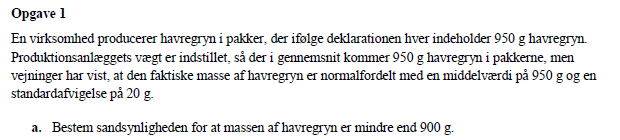

clc; clear;

% Normalfordelt med 
mu = 950;
stdafv = 20;

P_mindre_end_900g = normcdf(900, mu, stdafv)

P_mindre_end_900g = 0.0062

P_mellem_900g_og_1010g = normcdf(1010, mu, stdafv) - normcdf(900, mu, stdafv)

P_mellem_900g_og_1010g = 0.9924

Der skal standardiseres


$$z_{0.03} = \frac{x-\mu}{\sigma}$$


syms mu

z0 = norminv(0.03)

z0 = -1.8808


eq = z0 == (950 - mu)/stdafv;

mu = solve(eq, mu);
mu = vpa(mu,6)

$$mu = 987.616$$

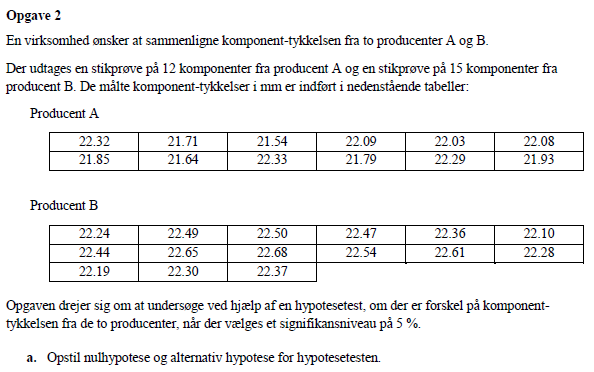

H0: tykkelse_A = tykkelse_B

Ha: tykkelse_A =/= tykkelse_B

Der er altså tale om en 2 sidet test på middelværdien

Det er ikke angivet at dataet et normalfordelt, og eftersom der er færre end 30 datapunkter, bruges der en t-fordeling til at gennemføre testen. 

Der bruges et script jeg selv har skrevet til udførsel af testen, der er inkluderet nederst i dokumentet, samt afleveret med eksamen.

Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\frac{\alpha }{2}\,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}}{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

    "Input 1"       21.967        0.072206       0.26871           12     
    "Input 2"       22.415         0.02947       0.17167           15     

    Frihedsgrader    Pooled varians    Pooled spredning    Nedre grænse    Øvre grænse    Teststatistik     p-værdi      h-værdi
    _____________    ______________    ________________    ____________    ___________    _____________<

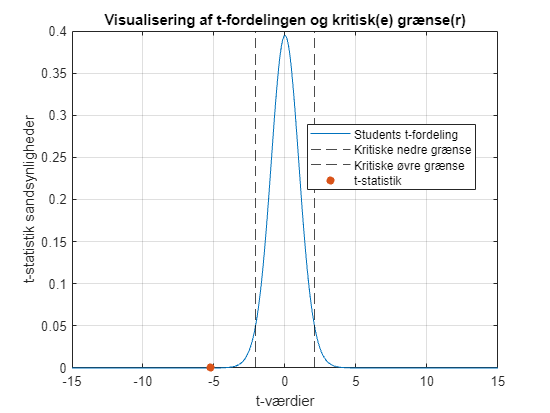

Da h = 1 forkastes nulhypotesen
Ydermere ses det også at t-værdien -5.2647 overstiger den kritiske grænse på -2.0595


clc; clear;
data = importdata("Data_M4STI1_2021F.xlsx").data;
prod_A = data(1:12,2);
prod_B = data(13:end,2);

OP = ttest2popMiddelInd(prod_A, prod_B,"both", 95,[]);

Det ses tydeligt, at på et 5% signifikansniveau, skal H0 hypotesen om at de har samme tykkelse, forkastes.

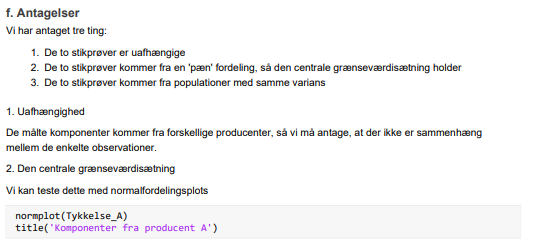

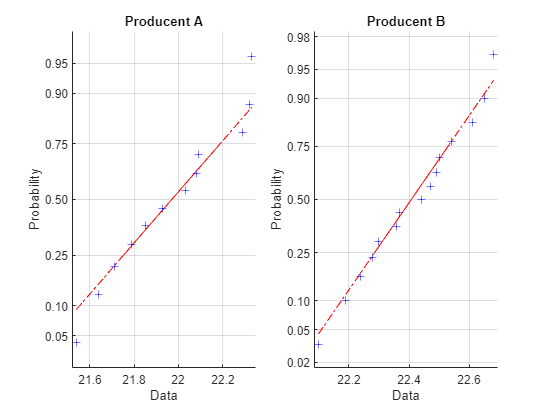


subplot(1,2,1)

normplot(prod_A)
title("Producent A")

subplot(1,2,2)

normplot(prod_B)
title("Producent B")

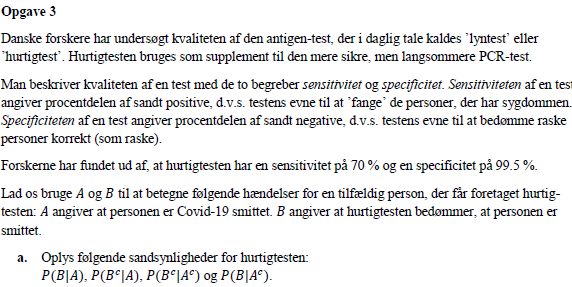

clc; clear;

% A angiver personen er smittet
% B angiver at hurtigtesten bedømmer at personen er smittet

A = 0.7

A = 0.7000

B = 0.995

B = 0.9950


P_B_givet_A = A

P_B_givet_A = 0.7000

P_Bc_givet_A = 1 - P_B_givet_A

P_Bc_givet_A = 0.3000

P_Bc_givet_Ac = B

P_Bc_givet_Ac = 0.9950

P_B_givet_Ac = 1 - B

P_B_givet_Ac = 0.0050

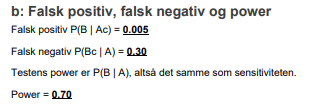

n = 1e4

n = 10000

smit = 0.2;

n_falsk_pos = n*(1-smit)*P_B_givet_Ac % 10 stk

n_falsk_pos = 40.0000


proc_falsk_pos = n_falsk_pos/(n*smit)

proc_falsk_pos = 0.0200



proc_falsk_neg = n*A*P_B_givet_A

proc_falsk_neg = 4900

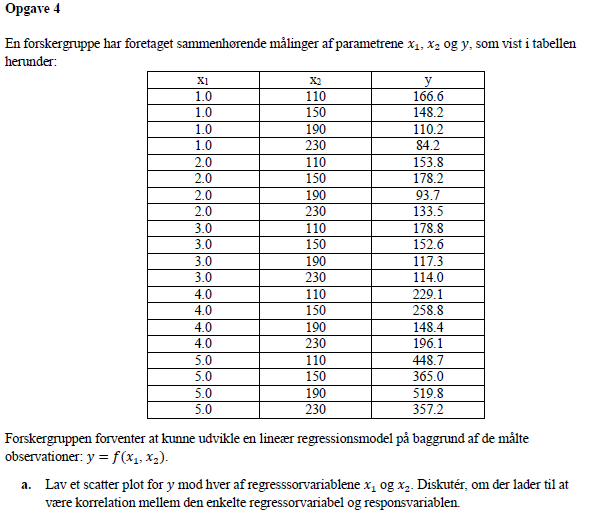

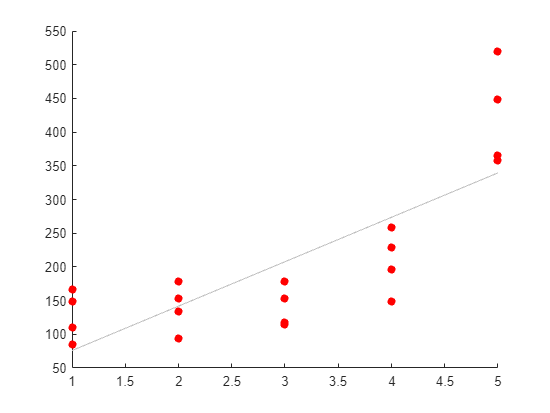

clc; clear;
data = importdata("Data_M4STI1_2021F.xlsx").data;
data = data(1:20,5:end);

x1 = data(:,1);
x2 = data(:,2);
y = data(:,3);

figure

scatter(x1,y,"filled","ro")
lsline

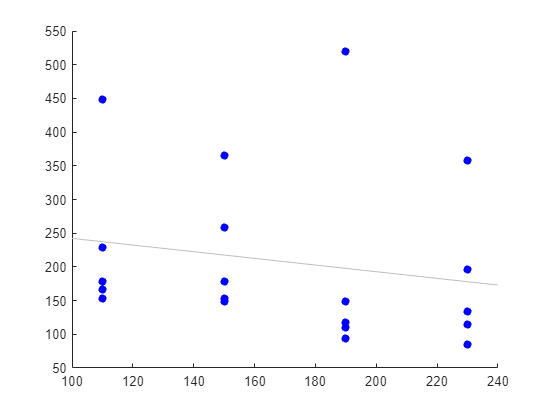


figure

scatter(x2,y,"filled","bo")
lsline

mdl = fitlm([x1,x2],y)

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     94.094      76.163     1.2354       0.23347
    x1              65.905      12.058     5.4659    4.1848e-05
    x2             -0.4947     0.38129    -1.2974       0.21182


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 76.3
R-squared: 0.65,  Adjusted R-Squared: 0.609
F-statistic vs. constant model: 15.8, p-value = 0.000134

Funktionsudtrykket bliver

y ~ 94.094 + 65.905*x1 -0.4947*x2

mdl2 = fitlm([x1,x2],y,'y~x1+x2+x1:x2')

mdl2 = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    ________    _______

    (Intercept)      128.14     161.73     0.79227    0.43979
    x1               54.557     48.764      1.1188    0.27974
    x2             -0.69495    0.92007    -0.75532    0.46103
    x1:x2           0.06675    0.27741     0.24062    0.81291


Number of observations: 20, Error degrees of freedom: 16
Root Mean Squared Error: 78.5
R-squared: 0.651,  Adjusted R-Squared: 0.586
F-statistic vs. constant model: 9.96, p-value = 0.000608

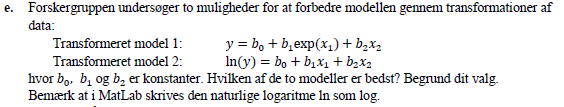

trans_mdl1 = fitlm([exp(x1) x2],y)

trans_mdl1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      196.4      36.705     5.3507    5.2967e-05
    x1              2.0456     0.16881     12.118    8.6638e-10
    x2             -0.4947     0.20395    -2.4256      0.026704


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 40.8
R-squared: 0.9,  Adjusted R-Squared: 0.888
F-statistic vs. constant model: 76.4, p-value = 3.21e-09


trans_mdl2 = fitlm([x1 x2],log(y))

trans_mdl2 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        4.8889      0.27952      17.49     2.645e-12
    x1                0.28482     0.044251     6.4364    6.1464e-06
    x2             -0.0031888    0.0013993    -2.2788      0.035872


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 0.28
R-squared: 0.733,  Adjusted R-Squared: 0.701
F-statistic vs. constant model: 23.3, p-value = 1.34e-05

res = ResidualMorten(trans_mdl1,data,"nej");

res.levlimit_formel

ans = "k*(k+1)/n"

res.lev_limit

ans = 0.3000


res.data2

ans = 1×4 table
    Regressorer    Datapunkter    Løftepunkt max    R-student max
    ___________    ___________    ______________    _____________

         2             20              0.3                3      


res.data

ans = 20×7 table
    Regressor 1    Regressor 2    Afhængig variabel    Hat-diagonal    R-student    Løftestangspunkter    Outliers
    ___________    ___________    _________________    ____________    _________    __________________    ________

         1             110              166.6             0.17304        0.50235            0                0    
         1             150              148.2            0.093043        0.51483            0                0    
         1             190              110.2            0.093043       0.055788            0                0    
         1             230               84.2             0.17304       -0.10409            0                0    
         2             110              153.8         